# Válogatott modellek a matematikai biológiában

# 1. gyakorlat

## Leslie féle stabilizálódó korfa

A populációt $n$ db korcsoportra osztjuk:

n = 100;

Születési és túlélési ráták:

s = sym('s',[1,n-1]);
b = sym('b',[1,n-1]);
syms lambda

L_sym = [ [0 , b] ; [diag(s) , zeros(n-1,1)] ];

A reprodukciós ráta:

R_sym = cumprod(s) * b.';

g = 1:n-1;
s = sin(0.023*g+0.8)';

min_age = 24;
max_age = 55;
b = [zeros(min_age,1) ; hann(max_age - min_age) ; zeros(n-max_age-1,1)];
R = cumprod(s)' * b

R = 0.4736

Normalizálom, hogy a reprodukciós ráta éppen 1 legyen:

b = b / R;

R = cumprod(s)' * b

R = 1

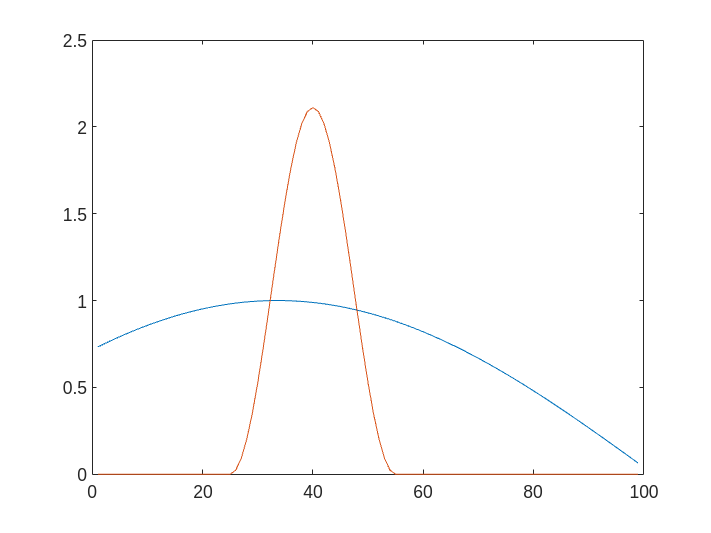

fig = figure(1);
fig.Visible = 'on';
plot(g,[s,b])

#### Populációdinamika szimulációja

L = [ [0 , b'] ; [diag(s) , zeros(n-1,1)] ]

L =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0231    0.0913    0.2016    0.3493    0.5278    0.7295    0.9453    1.1660    1.3819    1.5835    1.7621    1.9097    2.0201    2.0883    2.1113    2.0883    2.0201    1.9097    1.7621    1.5835    1.3819    1.1660    0.9453    0.7295
    0.7332         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

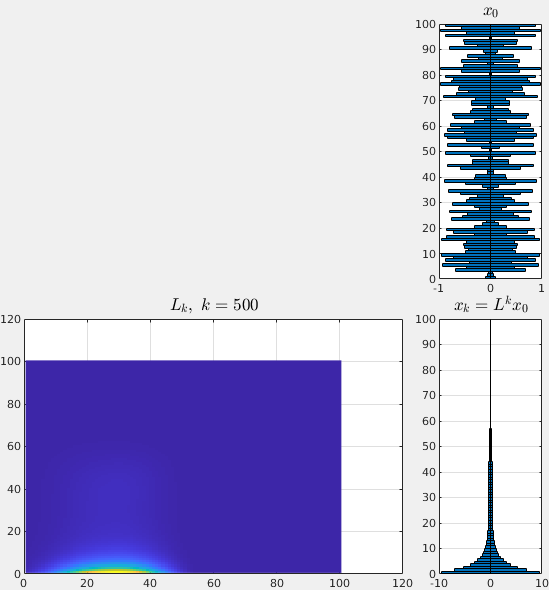

% Gr = digraph(L');
% Pl_Gr = plot(Gr);
x0 = rand(n,1);
T = 500;

fig = figure(123);
fig.Position(3:4) = [555,600];
fig.Visible = 'on';

Tl = tiledlayout(2,4,"TileSpacing","tight","Padding","tight","TileIndexing","rowmajor");

ax1 = nexttile(4); hold on, grid on, box on
Br0 = barh(0.5:n,[x0 -x0],1,'stacked');
Br0(2).FaceColor = Br0(1).FaceColor;
ylim([0,n])
title('$x_0$','Interpreter','latex','FontSize',12)

ax2 = nexttile(5,[1,3]); hold on, grid on, box on;
Img = imagesc(L);
Tl = title("$L_k,~ \makebox[2cm]{$k = 1\hfill$}$",'Interpreter','latex','FontSize',12);

ax3 = nexttile(8); hold on, grid on, box on;
Brn = barh(0.5:n,L*[x0 -x0],1,'stacked');
Brn(2).FaceColor = Brn(1).FaceColor;
ylim([0,n])
title('$x_k = L^k x_0$','Interpreter','latex','FontSize',12)

Ak = eye(n);
for k = 1:T
    Ak = Ak*L;
    xk = Ak*x0;
    se_hatv = eig(Ak);

    Brn(1).YData = xk;
    Brn(2).YData = -xk;
    
    Img.CData = Ak;

    Tl.String = "$L_k,~ k = " + num2str(k) + "$";
    drawnow
end